%The following code demonstrates the debugging process used to show that 
% the algebraic method can perfectly recover the missing data when the 
% gap is 2 (noise free)
% Zimu Huo

clear;
clc;

addpath("util/")
addpath("svd/")

addpath("bart/")


N = 64;              % FOV    
ny = N; nx = N; nz = N;
nc = 4;
gap = 0; % set 0 for now to get ground truth


brain = get_brain_phantom(100);
brain = brain(1:2:end,1:2:end,1:2:end);
brain = brain(1:2:end,1:2:end,1:2:end);

% volumeViewer(abs(brain));

traj = piccini_phyllotaxis(floor(N * N), 1);
traj = traj2points(traj, N, 2);
traj = permute(traj, [3, 2, 1]);
traj1 = traj(:,:,1);
traj = cat(3, traj1, -traj1);
[ndim, nRO, nTR]=size(traj);
sensMap = coilmap([N,N,N], nc, 64);
coil_image = repmat(brain,1,1,1,nc) .* sensMap;
object_mask = coil_image;
object_mask(object_mask > 0) = 1; 
% volumeViewer(sos(coil_image))
clear sensMap

%% ground_truth
disp("computing ground truth")

computing ground truth


obj = nufft_3d(traj,N,'gpu',2);
data = obj.fNUFT(coil_image);
ground_truth = obj.iNUFT(data, 0);

%% Noisy SNR 20 std 85; SNR 15 std 150 ; SNR 10 std 260 ; SNR 5 std = 500
std = 0;
disp("computing noisy realisation")

computing noisy realisation


noise = gaussian_noise(size(data),0, std); 
noisy_data = data + noise;                                                                                                                          
SNR = snr(abs(ground_truth), obj.iNUFT(noise, 0));
noisy_images = obj.iNUFT(noisy_data, 0);
l2(noisy_images , ground_truth)

ans = 0


%% zero_filled
disp("computing zero filled")

computing zero filled


unfilled_zte_data = reshape(noisy_data, nRO, nTR, nc);
obj.nTR = nTR;
obj.nRO = nRO;
obj.gap = gap;
unfilled_zte_data(1:gap,:,:) = 0;



%% 
disp("computing algebraic")

computing algebraic


data = gather(unfilled_zte_data(:,:,1));

l = nRO * 2- 1; 
T = ones(l, 1);
T(l/4:l/4+l/2) = 0;

T = diag(T);

C = ones(l, 1);
C(l/2-gap/2:l/2+gap) = 0;

C = diag(C);

F = dftmtx_custom(l);
F_inv = pinv(F);
A = C * F * T;
A_inv = F * pinv(A, 1e-3);

pos = (squeeze(data(:,1)));
neg = (squeeze(data(:,2)));
neg = neg(end:-1:1);
ground_truth_spoke = cat(1, neg(1:end-1), pos);

gap = 3; % 3 on 2 oversampled grid, 2 on nominal grid 
unfilled_zte_data(1:gap,:,:) = 0;
unfilled_zte_data = gather(unfilled_zte_data(:,:,1));
l = nRO * 2- 1; 
T = ones(l, 1);
T(l/4:l/4+l/2) = 0;

T = diag(T);

C = ones(l, 1);
C(l/2-gap/2:l/2+gap) = 0;

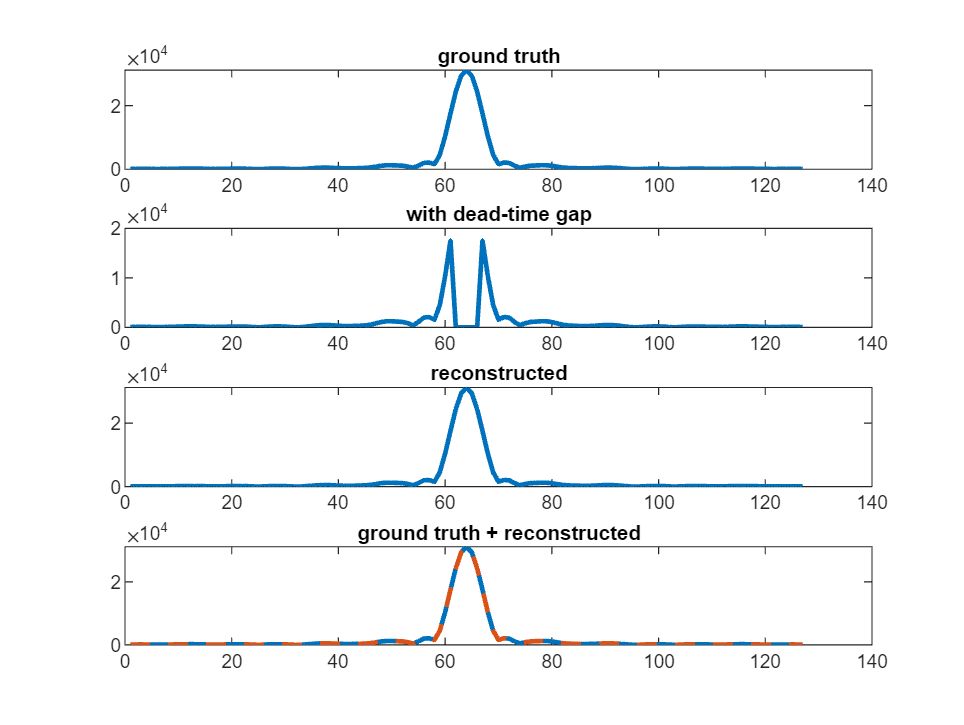

C = diag(C);

F = dftmtx_custom(l);
F_inv = pinv(F);
A = C * F * T;
A_inv = F * pinv(A, 1e-6);

pos = (squeeze(unfilled_zte_data(:,1)));
neg = (squeeze(unfilled_zte_data(:,2)));
neg = neg(end:-1:1);
combined = cat(1, neg(1:end-1), pos);
algebraic_spoke = A_inv * combined; 

figure()
subplot(411)
plot(abs(ground_truth_spoke), LineWidth=2)
title("ground truth")
subplot(412)
plot(abs(combined),  LineWidth=2)
title("with dead-time gap")
subplot(413)
plot(abs(algebraic_spoke), LineWidth=2)
title("reconstructed")
subplot(414)
plot(abs(ground_truth_spoke), LineWidth=2)
hold on
plot(abs(algebraic_spoke),'--', LineWidth=2)
title("ground truth + reconstructed")